% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time and conditions.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% 1- ICA on preprocessed epoched data
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %

Processing G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


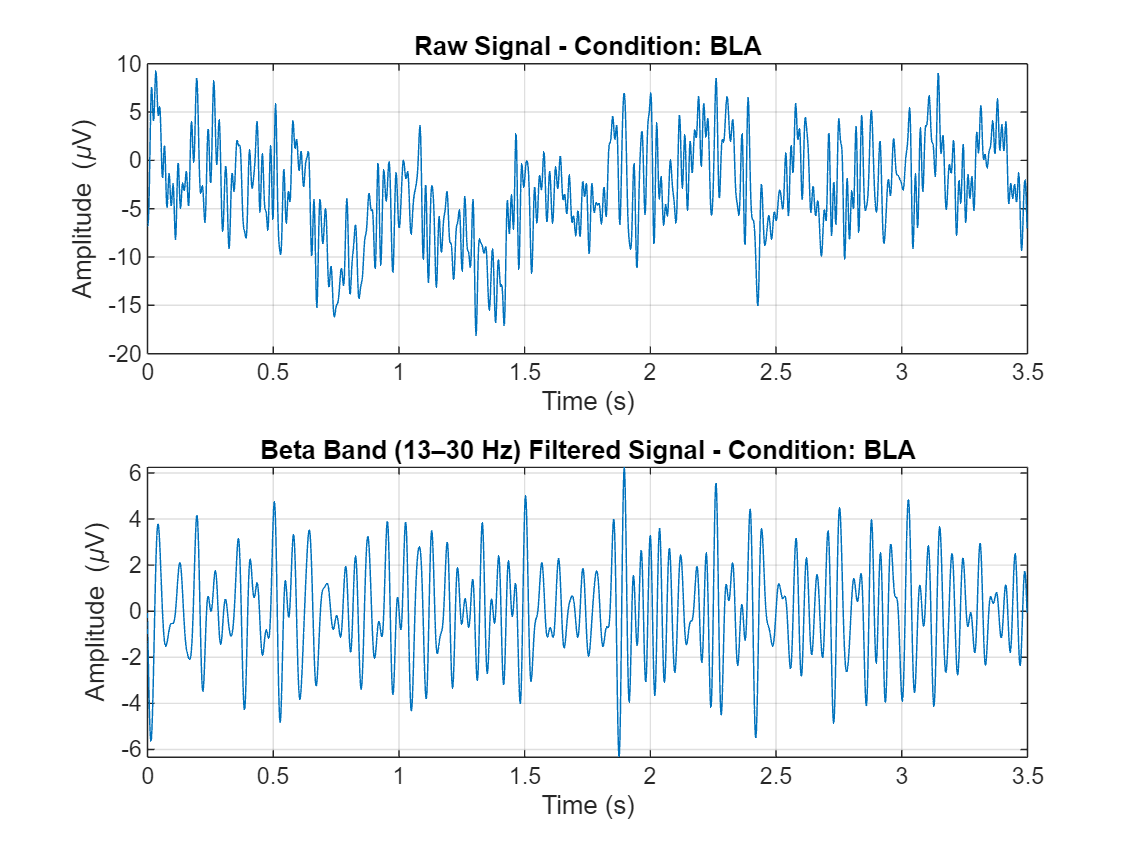

Processing G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


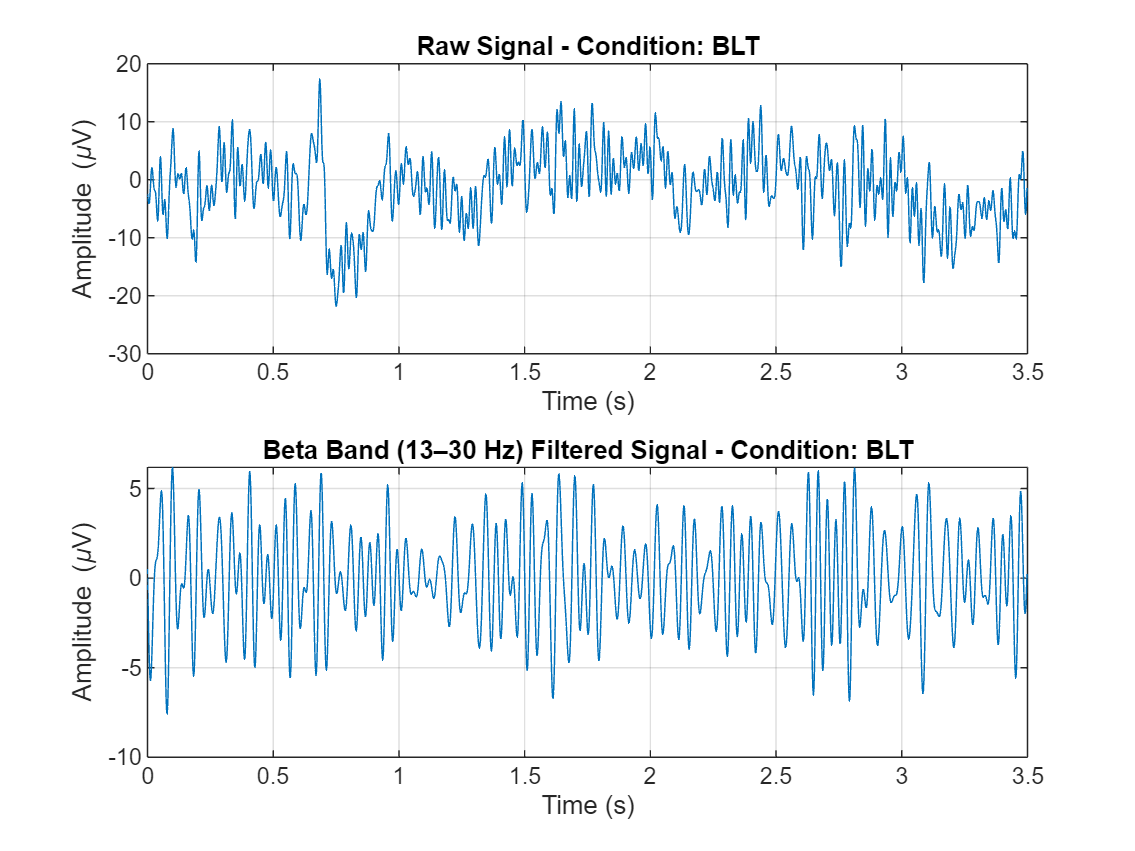

Processing G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


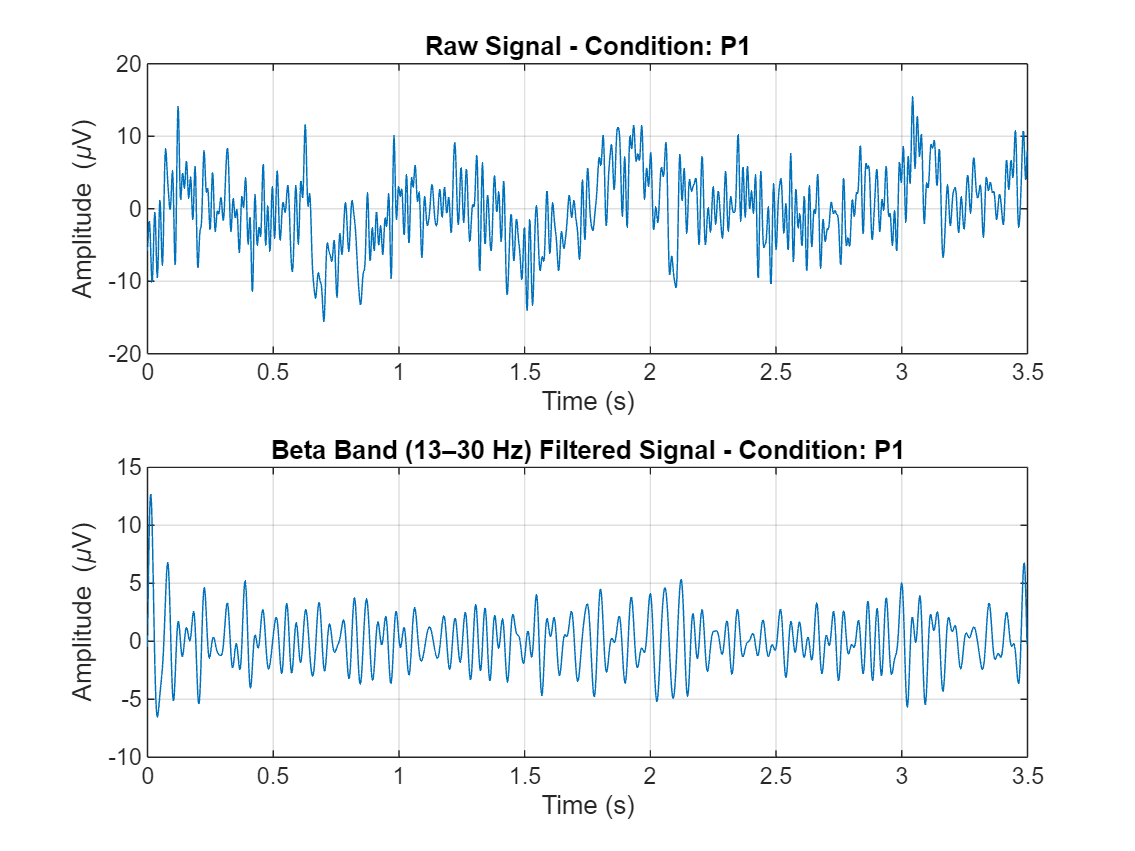

Processing G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


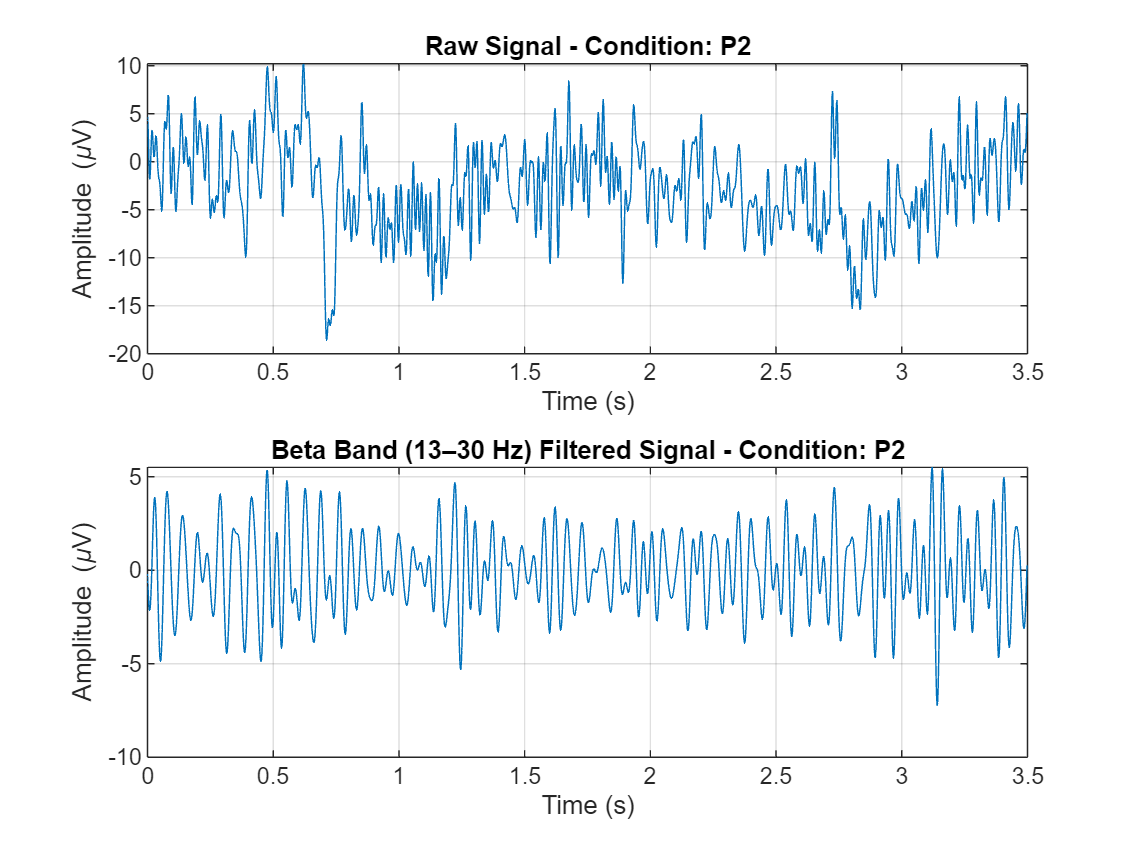

Processing G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


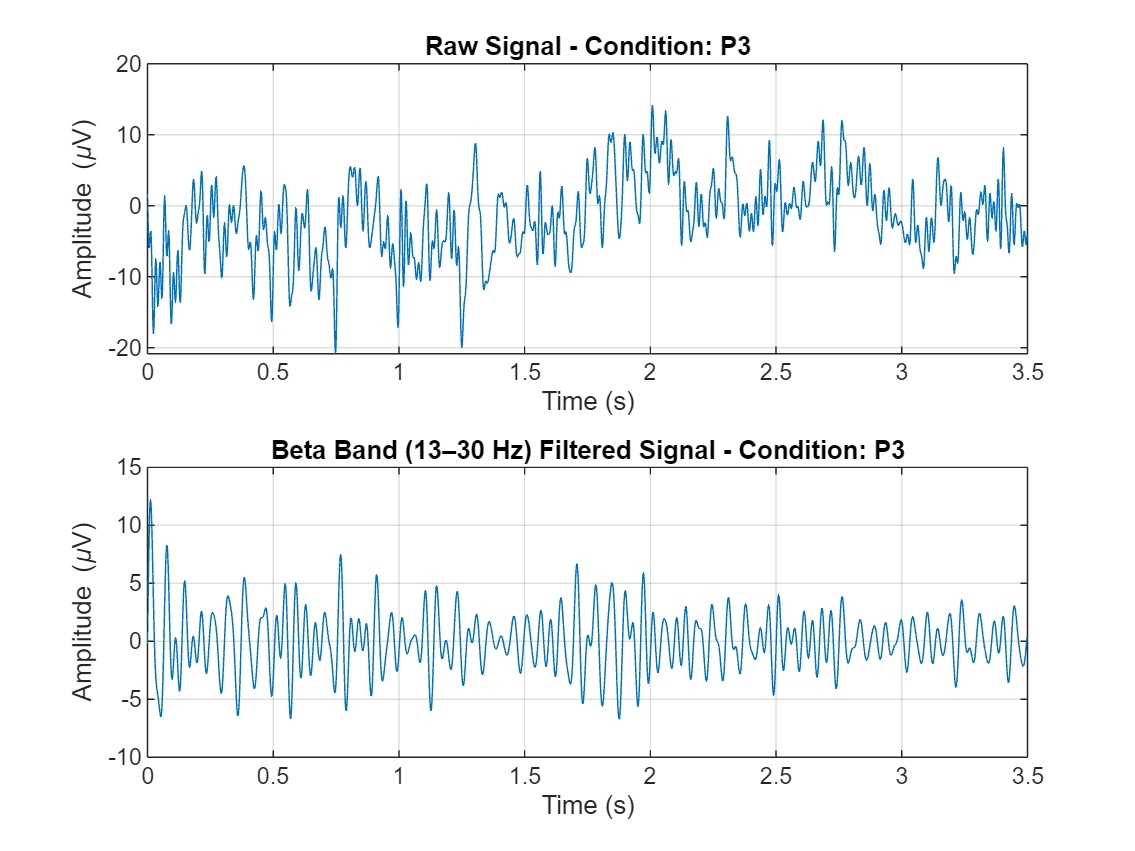

% 2- PCA 
% - 2.1 PCA across condition: making a giant matrix from channel x time x
% trial x condition into ch x (time-trial-conidtion)
num_ch= 32; 
num_time_samples = 1792;
num_trials = 60; 
num_conditions = length(conditions);
beta_signal_giant = zeros(num_ch,  num_time_samples *num_trials * num_conditions);
col_start = 1;
% Loop over each condition
for i = 1:length(conditions)
    condition = conditions{i};
    input_path_condition = fullfile(input_path, condition);
    output_path_condition = fullfile(output_path, condition);
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path,'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path,'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end

    if ~exist(output_path_condition, 'dir')
        mkdir(output_path_condition);
    end
    
    % Get all .set files in the directory
    set_files = dir(fullfile(input_path_condition, '*.set'));
    
    % Loop over each subject's dataset
    %for j = 1:length(set_files)
        file_path = fullfile(input_path_condition, set_files(1).name);
        fprintf('Processing %s...\n', file_path);
        EEG = pop_loadset(file_path);
        
        % Extract relevant parameters
        fs = EEG.srate; % Sampling rate
        % time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)
    
        % Select odd or even epochs based on condition
        if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
            epoch_trials = 1:2:EEG.trials; % Odd epochs
        elseif strcmp(condition, 'BLT')
            epoch_trials = 2:2:EEG.trials; % Even epochs
        else
            error('Condition not recognized. Please specify "BLA" or "BLT".');
        end
    
        num_trials = length(epoch_trials);
        data = EEG.data(:, :, epoch_trials);
    
        % Bandpass filter beta band (13-30 Hz)
        beta_band = [13 30];
        beta_signal = zeros(size(data)); % Preallocate
        for epoch = 1:size(data, 3)
            beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)';
        end
        
        % Plot one trial (e.g., the first trial) from one channel (e.g., channel 1) for visualization
        trial_to_plot = 1;
        channel_to_plot = 18;
        
        raw_signal = squeeze(data(channel_to_plot, :, trial_to_plot));
        filtered_signal = squeeze(beta_signal(channel_to_plot, :, trial_to_plot));
        time_vector = (0:length(raw_signal)-1) / fs;  % assuming time starts at 0
        
        figure('Name', ['Condition: ' condition], 'NumberTitle', 'off');
        subplot(2,1,1);
        plot(time_vector, raw_signal);
        title(['Raw Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;
        
        subplot(2,1,2);
        plot(time_vector, filtered_signal);
        title(['Beta Band (13–30 Hz) Filtered Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;

        beta_signal_reshape = reshape(beta_signal, num_ch,num_time_samples*num_trials );
        beta_signal_giant(:,col_start:num_time_samples *num_trials*i) = beta_signal_reshape;
        col_start = 1+num_time_samples *num_trials*i;

    

end

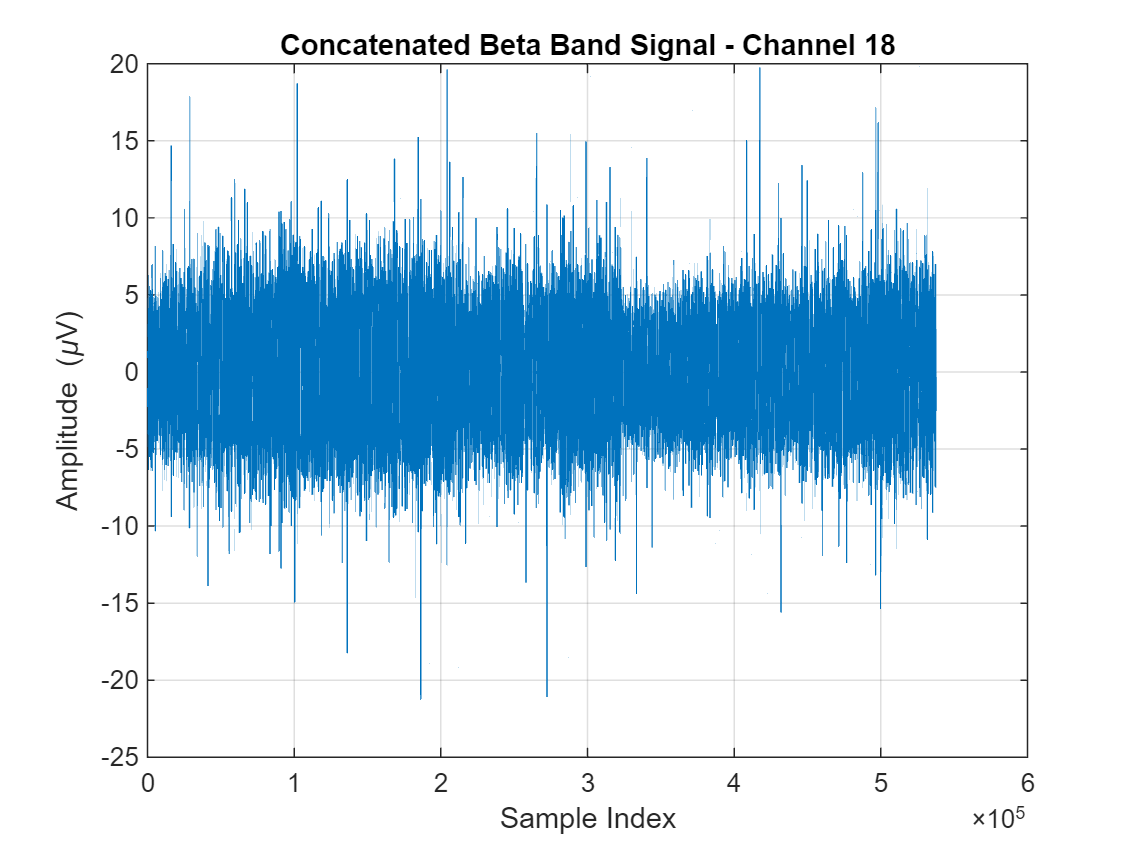

% Plot one example channel from beta_signal_giant
channel_to_plot = 18;
figure('Name', 'Beta Signal Giant (Concatenated)', 'NumberTitle', 'off');
plot(beta_signal_giant(channel_to_plot, :));
title(['Concatenated Beta Band Signal - Channel ' num2str(channel_to_plot)]);
xlabel('Sample Index');
ylabel('Amplitude (\muV)');
grid on;


disp(size(beta_signal_giant));

          32      537600



[coeff, score, ~, ~, varExpl] = pca(beta_signal_giant');

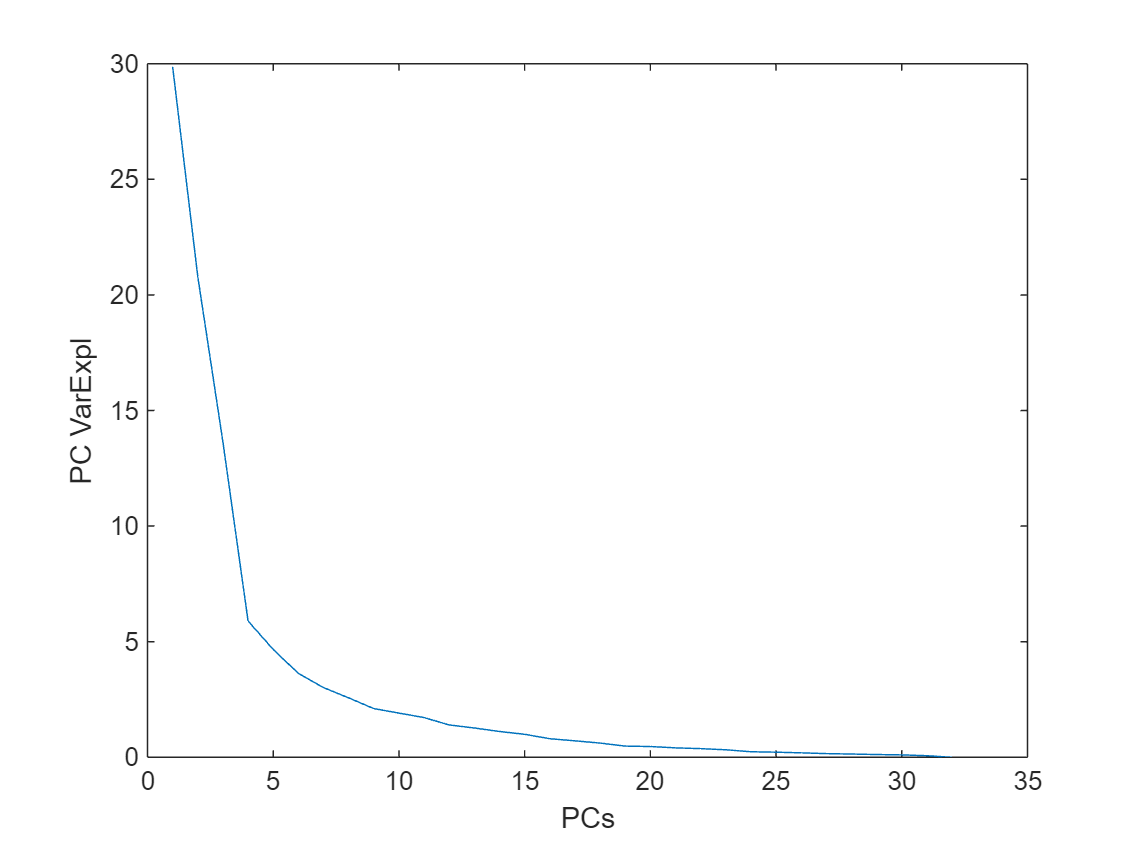

figure('Name','Explained Vairance'); 
plot(varExpl);
ylabel('PC VarExpl');
xlabel('PCs');


threshold = 85;  % Target explained variance threshold

% Preallocate result
pc_at_85 = zeros(1, 1);

cum_sum_varExpl = cumsum(varExpl);  % Compute cumulative sum for this trial
idx = find(cum_sum_varExpl >= threshold, 1, 'first');     % Find first PC where cumulative sum ≥ 85
if ~isempty(idx)
    pc_at_85 = idx;
else
    pc_at_85 = NaN;  % If 85% is never reached
end

display(pc_at_85);

pc_at_85 = 9

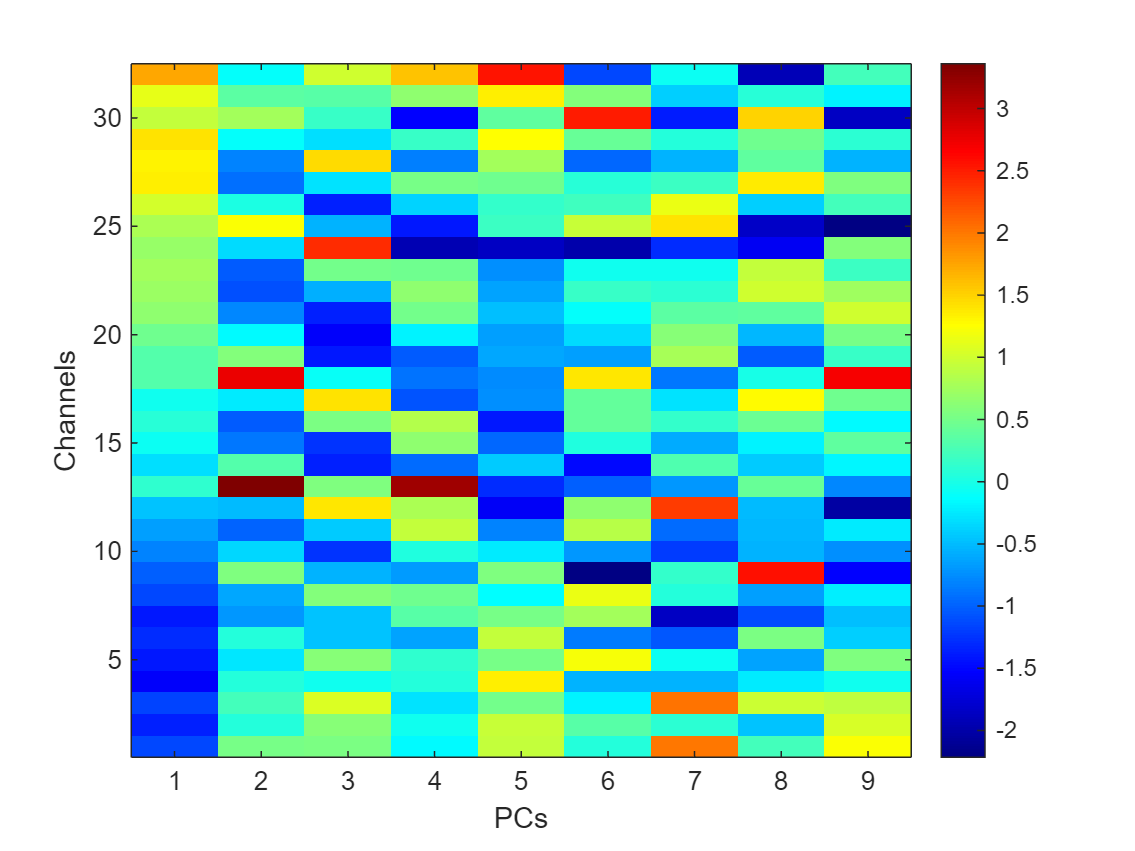

coeff_z = zscore(coeff);
figure();
imagesc(coeff_z(:,1:pc_at_85));  % PCs on y-axis
set(gca, 'YDir', 'normal');  % Ensure y-axis is oriented correctly
colormap jet;
colorbar;

xlabel('PCs');
ylabel('Channels');

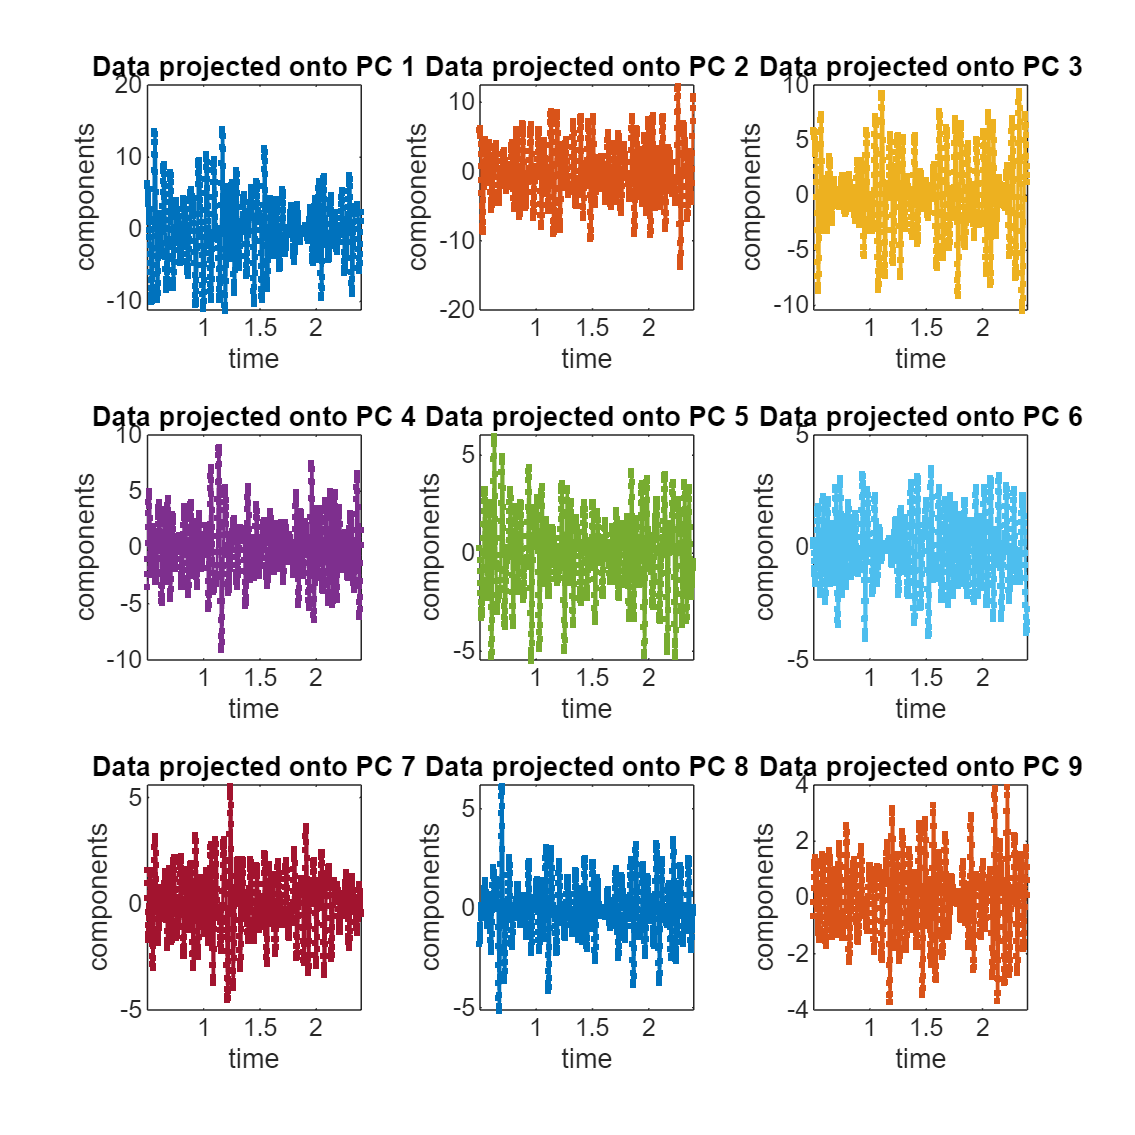


figure('Position', [100, 100, 1200, 1200]); % [x, y, width, height]
t = tiledlayout(3,3);
pc_colors = lines(pc_at_85);
idx_range = time_vector>0.50 & time_vector<=2.4;
for i=1:pc_at_85
    hold on
    nexttile;
    plot(time_vector(idx_range), score(idx_range,i), '.-', 'linewidth', 1,'Color',pc_colors(i,:))
    title(['Data projected onto PC ',num2str(i)])
    ylabel('components')
    xlabel('time')
    
end

% Reconstruction error based on first 9 PCs:
% Number of PCs to use for reconstruction
num_pcs = pc_at_85;

% Reconstruct the data using only the first 9 PCs
reconstructed = score(:, 1:num_pcs) * coeff(:, 1:num_pcs)';

% Compute the mean squared reconstruction error
original_data = beta_signal_giant';  % Original shape: [samples x features]
reconstruction_error = mean((original_data(:) - reconstructed(:)).^2);

fprintf('Reconstruction error using first %d PCs: %.4f\n', num_pcs, reconstruction_error);

Reconstruction error using first 9 PCs: 0.3991


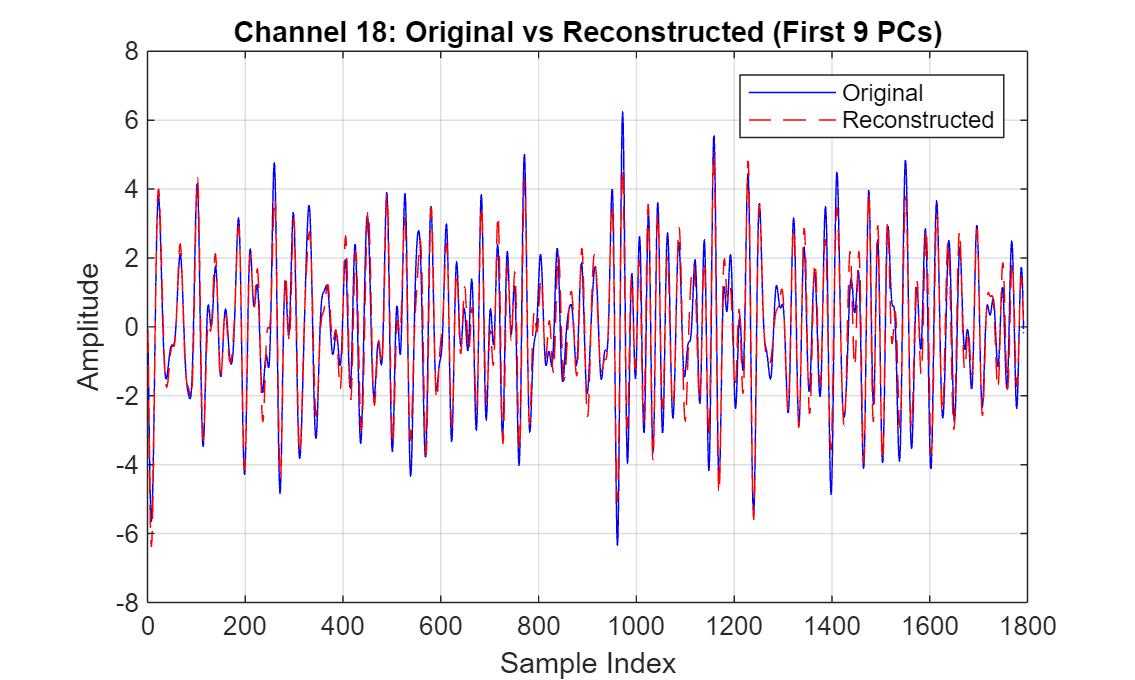


example_channel = 18;
figure('Position', [100, 100, 1000, 600]);
plot(original_data(1: length(time_vector), example_channel), 'b'); hold on;
plot(reconstructed(1: length(time_vector), example_channel), 'r--');
legend('Original', 'Reconstructed');
title(sprintf('Channel %d: Original vs Reconstructed (First %d PCs)', example_channel, num_pcs));
xlabel('Sample Index');
ylabel('Amplitude');
grid on;